For den første kompressor GP18CB/SC21G

clear
T_1 = -20; %C
T_4 = -10; %C


%%%%%%%%%%%%%%          R134a        %%%%%%%%%%%%%%%%%%%%%
%                         R1

L = 7%sym('L', 'positive') %, 'positive'

L = 7

% syms L

nu = 0.000001511; %m^2 / s

eta_1 = 0.00001022; %kg/(m*s)

q_m = 0.00338; %kg/s


d_1 = (9.52 - 2 * 0.8) / 1000 % m %indre diameter af kobber rør

d_1 = 0.0079

g = 9.82; % m/s^2

lambda_1 = 0.01036 %[W/m-K]

lambda_1 = 0.0104

r_fordamp = 211.2 * 1000% J/kg%m * l_fd

r_fordamp = 211200

Re_1 = q_m * d_1 / (pi/4 * d_1^2 * eta_1)

Re_1 = 5.3168e+04

K_f = r_fordamp / (L * g) 

K_f = 3.0724e+03

NUs_1 = 0.0075 * (Re_1^2 * K_f )^0.40

NUs_1 = 1.1235e+03


alpha_1 = NUs_1 * lambda_1 / d_1;
alpha_1_ = vpa(alpha_1,5)

$$alpha\_1\_ = 1469.6$$


A_1 = pi*d_1*L

A_1 = 0.1742


R_1 = vpa(1 / (alpha_1 * A_1), 3) % K/W

$$R\_1 = 0.00391$$

%%%%%%%%%%%%%%%%%%%%%  Kobber rør   %%%%%%%%%%%%%
%                         R2

r_1 = d_1/2 % m % indre radius

r_1 = 0.0040

d_2 = 9.52 / 1000 % m ydre diamter af rør

d_2 = 0.0095

r_2 = d_2 /2  % m % ydre radius

r_2 = 0.0048


lambda_2 = 372; % W/(m*K) Tabel 10.11 i thermo bog version 4


R_2 = (r_2 / r_1) / (lambda_2 * 2 * pi * L)

R_2 = 7.3467e-05



%%%%%%%%%%%%%%%%%%%%    Brine  20% saltblanding NaCl  %%%%%%%%%%%%%%%%%
%                       R3

T_3 =  -18; % C gæt

nu_3 = 0.000003921; %[m^2/s]
c_p_3 = 3.354 * 1000; %[J/Kg * K]
rho_3 = 1162; % kg/m^3
lambda_3 = 0.5172; % W/(m*K)

a_3 = lambda_3 / (c_p_3 * rho_3)

a_3 = 1.3271e-07

beta_3 =  0.000021; %1/K  % chat bot


eta_3 = nu_3 * rho_3

eta_3 = 0.0046


%19l/min

s =  19 / (60 * 10 * 10 * 10); %pumpen  kan lever 19L/min
% min1/s60
% 1m^3/L1000
d_pumpe = 0.01; % m

d_brine1 = 0.18;
A_brine1 = pi * (d_brine1/2)^2;
d_brine2 = 0.20;
A_brine2 = pi * (d_brine2/2)^2;

% A_pumpe = A_brine2 - A_brine1
% A_pumpe = 0.06
A_pumpe = pi * (d_pumpe/2)^2

A_pumpe = 7.8540e-05


c = 0.5%s / A_pumpe %pga sug gange med 2

c = 0.5000


% c = 1

Re_3 = c / (pi/4 * d_2^2 * eta_3)

Re_3 = 1.5417e+06

vpa(Re_3,6)

$$ans = 1541710.0$$



Pr_3 = eta_3 * c_p_3 / lambda_3

Pr_3 = 29.5466

Pr_v3 = Pr_3

Pr_v3 = 29.5466

% NUs_3 = (0.60 + (0.387 * Ra^(1/6)) / (1 + (0.559/Pr_3)^(9/16))^(8/27) )^2
C_3 = 0.26;
m = 0.6;
n = 0.36;



NUs_3 = C_3 * Re_3^m * Pr_3^n * (Pr_3/Pr_v3)^(1/4)

NUs_3 = 4.5411e+03


alpha_3 = NUs_3 * lambda_3 / d_2 

alpha_3 = 2.4671e+05


A_3 = pi * d_2 * L

A_3 = 0.2094


R_3 = 1 / (alpha_3 * A_3)

R_3 = 1.9361e-05

TOTAL udregninger

Phi_0 = 500%w 

Phi_0 = 500



R_tot_eq1 = R_1 + R_2  +  R_3 %+ R_3

$$R\_tot\_eq1 = 0.0039995880075063892985923804518356$$

R_tot_eq2 = (T_4 - T_1) / Phi_0

R_tot_eq2 = 0.0200



% L_fordamp = solve(R_tot_eq1 == R_tot_eq2, L)


For den nye kompressor GS34MFX

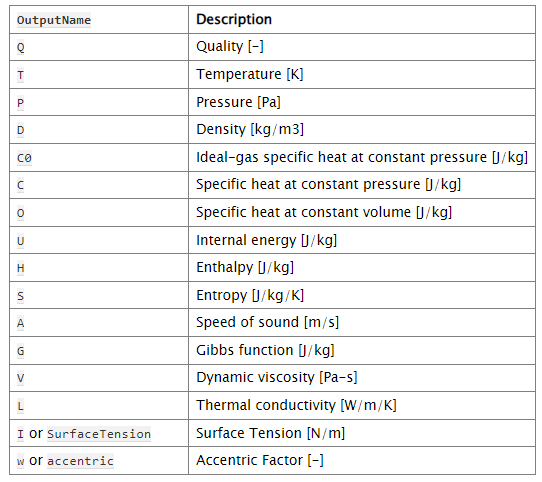

clear all
clf

% Importer CoolProp-modul
CoolProp = py.importlib.import_module('CoolProp.CoolProp');

% Stof (kan ændres efter behov)
fluid = 'R134a';

T_1 = -10 + 273.15 %C

T_1 = 263.1500

T_4 = -20 + 273.15 %C

T_4 = 253.1500

P_low = 1.33 * 1e5

P_low = 133000

h_1 = 389428;
h_4 = 241463;

%%%%%%%%%%%%%%          R134a        %%%%%%%%%%%%%%%%%%%%%
%                         R1

% L = 7%sym('L', 'positive') %, 'positive'
syms L
% L = 6.7 %m

nu_1 =  CoolProp.PropsSI('V', 'P', P_low, 'T', T_1, fluid)%0.000001511; %m^2 / s

nu_1 = 1.0409e-05

nu_4 =  CoolProp.PropsSI('V', 'P', P_low, 'T', T_4, fluid)

nu_4 = 3.4759e-04

nu = (nu_1 + nu_4)/2

nu = 1.7900e-04


rho_1 = CoolProp.PropsSI('D', 'T', T_1, 'P', P_low, fluid)

rho_1 = 6.4877

rho_4 = CoolProp.PropsSI('D', 'T', T_4, 'P', P_low, fluid)

rho_4 = 1.3583e+03

rho = (rho_1 + rho_4)/2

rho = 682.3769


eta = nu * rho;

% eta_1 = 0.00001022; %kg/(m*s)

q_m = 0.008497; %kg/s


d_1 = (9.52 - 2 * 0.8) / 1000 % m %indre diameter af kobber rør

d_1 = 0.0079

g = 9.81; % m/s^2

lambda_1 =  CoolProp.PropsSI('D', 'T', T_1, 'P', P_low, fluid)%0.01036 %[W/m-K]

lambda_1 = 6.4877

lambda_4 =  CoolProp.PropsSI('D', 'T', T_4, 'P', P_low, fluid)

lambda_4 = 1.3583e+03

lambda = (lambda_1 + lambda_4)/2

lambda = 682.3769


r_fordamp = 211.2 * 1000% J/kg%m * l_fd

r_fordamp = 211200



Re_1 = q_m * d_1 / (pi/4 * d_1^2 * eta)

Re_1 = 11.1835


K_f = r_fordamp / (L * g) 

$$K\_f = \frac{7040000}{327\,L}$$


NUs_1 = 0.0075 * (Re_1^2 * K_f )^0.40

$$NUs\_1 = \frac{3\,{\left(\frac{60506929960847335625}{22471268892672\,L}\right)}^{2/5}}{400}$$


alpha_1 = NUs_1 * lambda / d_1;

alpha_1_ = vpa(alpha_1,5)

$$alpha\_1\_ = 646.19\,{\left(\frac{2.6926e+6}{L}\right)}^{2/5}$$


A_1 = pi*d_1*L

$$A\_1 = \frac{99\,\pi \,L}{12500}$$


R_1 = vpa(1 / (alpha_1 * A_1), 3) % K/W

$$R\_1 = \frac{0.0622}{L\,{\left(\frac{2.69e+6}{L}\right)}^{2/5}}$$

%%%%%%%%%%%%%%%%%%%%%  Kobber rør   %%%%%%%%%%%%%
%                         R2

r_1 = d_1/2 % m % indre radius

r_1 = 0.0040

d_2 = 9.52 / 1000 % m ydre diamter af rør

d_2 = 0.0095

r_2 = d_2 /2  % m % ydre radius

r_2 = 0.0048


lambda_2 = 372; % W/(m*K) Tabel 10.11 i thermo bog version 4


R_2 = (r_2 / r_1) / (lambda_2 * 2 * pi * L)

$$R\_2 = \frac{119}{73656\,L\,\pi }$$



%%%%%%%%%%%%%%%%%%%%    Brine  20% saltblanding NaCl  %%%%%%%%%%%%%%%%%
%                       R3


nu_3 = 0.000003921; %[m^2/s]
c_p_3 = 3.354 * 1000; %[J/Kg * K]
rho_3 = 1162; % kg/m^3
lambda_3 = 0.5172; % W/(m*K)

a_3 = lambda_3 / (c_p_3 * rho_3)

a_3 = 1.3271e-07

beta_3 =  0.000021; %1/K  % chat bot


eta_3 = nu_3 * rho_3

eta_3 = 0.0046


%19l/min

s =  19 / (60 * 10 * 10 * 10); %pumpen  kan lever 19L/min
% min1/s60
% 1m^3/L1000
d_pumpe = 0.01; % m

d_brine1 = 0.18;
A_brine1 = pi * (d_brine1/2)^2;
d_brine2 = 0.20;
A_brine2 = pi * (d_brine2/2)^2;

% A_pumpe = A_brine2 - A_brine1
% A_pumpe = 0.06
A_pumpe = pi * (d_pumpe/2)^2

A_pumpe = 7.8540e-05


c = 0.5%s / A_pumpe %pga sug gange med 2

c = 0.5000


% c = 1

Re_3 = c / (pi/4 * d_2^2 * eta_3)

Re_3 = 1.5417e+06

vpa(Re_3,6)

$$ans = 1541710.0$$



Pr_3 = eta_3 * c_p_3 / lambda_3

Pr_3 = 29.5466

Pr_v3 = Pr_3

Pr_v3 = 29.5466

% NUs_3 = (0.60 + (0.387 * Ra^(1/6)) / (1 + (0.559/Pr_3)^(9/16))^(8/27) )^2
C_3 = 0.26;
m = 0.6;
n = 0.36;



NUs_3 = C_3 * Re_3^m * Pr_3^n * (Pr_3/Pr_v3)^(1/4)

NUs_3 = 4.5411e+03


alpha_3 = NUs_3 * lambda_3 / d_2 

alpha_3 = 2.4671e+05


A_3 = pi * d_2 * L

$$A\_3 = \frac{119\,\pi \,L}{12500}$$


R_3 = 1 / (alpha_3 * A_3)

$$R\_3 = \frac{214748364800000}{504366679661581499\,L\,\pi }$$

TOTAL udregninger

Phi_0 = q_m * (h_4 - h_1)

Phi_0 = -1.2573e+03

R_tot = R_1 + R_2 + R_3

$$R\_tot = \frac{75837140437436998381}{37149632157153446890344\,L\,\pi }+\frac{0.06219629616862221155315637588501}{L\,{\left(\frac{2692635.21563720703125}{L}\right)}^{2/5}}$$



R_tot_eq1 = R_1 + R_2  +  R_3 %+ R_3

$$R\_tot\_eq1 = \frac{75837140437436998381}{37149632157153446890344\,L\,\pi }+\frac{0.06219629616862221155315637588501}{L\,{\left(\frac{2692635.21563720703125}{L}\right)}^{2/5}}$$

R_tot_eq2 = (T_4 - T_1) / Phi_0

R_tot_eq2 = 0.0080



L_fordamp = solve(R_tot_eq1 == R_tot_eq2, L)

$$L\_fordamp = 0.089679809057473464751472419025842$$